syms x(t) 
syms g h xo dxo real;
Dx = diff(x);

ode = diff(x,t,2) == g/h*x;

cond1 = x(0) == xo;
cond2 = Dx(0) == dxo;

conds = [cond1 cond2];


% Solve for symbolic solutions;

xSol(t) = dsolve(ode,conds);
xSol = simplify(xSol)

$$xSol(t) = \frac{{\mathrm{e}}^{\frac{t\,\sqrt{g\,h}}{h}}\,\left(\mathrm{dxo}\,h+\mathrm{xo}\,\sqrt{g\,h}\right)}{2\,\sqrt{g\,h}}-\frac{{\mathrm{e}}^{-\frac{t\,\sqrt{g\,h}}{h}}\,\left(\mathrm{dxo}\,h-\mathrm{xo}\,\sqrt{g\,h}\right)}{2\,\sqrt{g\,h}}$$

dxSol = diff(xSol)

$$dxSol(t) = \frac{{\mathrm{e}}^{\frac{t\,\sqrt{g\,h}}{h}}\,\left(\mathrm{dxo}\,h+\mathrm{xo}\,\sqrt{g\,h}\right)}{2\,h}+\frac{{\mathrm{e}}^{-\frac{t\,\sqrt{g\,h}}{h}}\,\left(\mathrm{dxo}\,h-\mathrm{xo}\,\sqrt{g\,h}\right)}{2\,h}$$


T = solve(xSol + xo, t, 'Real', true, "ReturnConditions",true);
T.conditions

$$ans = \begin{array}{l} 0<\sigma_{1}\wedge \mathrm{dxo}\,h+\mathrm{xo}\,\sqrt{g\,h}\neq 0\wedge \frac{\log\left(\sigma_{1}\right)}{\sqrt{g\,h}}\in \mathbb{R}\wedge \mathrm{dxo}\,h\neq \mathrm{xo}\,\sqrt{g\,h}\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{dxo}\,h-\mathrm{xo}\,\sqrt{g\,h}}{\mathrm{dxo}\,h+\mathrm{xo}\,\sqrt{g\,h}} \end{array}$$

T.t

$$ans = \frac{h\,\log\left(\frac{\mathrm{dxo}\,h-\mathrm{xo}\,\sqrt{g\,h}}{\mathrm{dxo}\,h+\mathrm{xo}\,\sqrt{g\,h}}\right)}{\sqrt{g\,h}}$$

% Solve for numerical solutions;

xo_num = -0.3;
dxo_num = 0.5;
g_num = 2;
h_num = 0.8;

xSol_num = subs(xSol,[xo, dxo, g,h],[xo_num, dxo_num, g_num, h_num])

$$xSol\_num(t) = -\frac{\sqrt{5}\,\sqrt{8}\,{\mathrm{e}}^{-\frac{\sqrt{5}\,\sqrt{8}\,t}{4}}\,\left(\frac{3\,\sqrt{5}\,\sqrt{8}}{50}+\frac{2}{5}\right)}{16}-\frac{\sqrt{5}\,\sqrt{8}\,{\mathrm{e}}^{\frac{\sqrt{5}\,\sqrt{8}\,t}{4}}\,\left(\frac{3\,\sqrt{5}\,\sqrt{8}}{50}-\frac{2}{5}\right)}{16}$$

dxSol_num = diff(xSol_num)

$$dxSol\_num(t) = \frac{5\,{\mathrm{e}}^{-\frac{\sqrt{5}\,\sqrt{8}\,t}{4}}\,\left(\frac{3\,\sqrt{5}\,\sqrt{8}}{50}+\frac{2}{5}\right)}{8}-\frac{5\,{\mathrm{e}}^{\frac{\sqrt{5}\,\sqrt{8}\,t}{4}}\,\left(\frac{3\,\sqrt{5}\,\sqrt{8}}{50}-\frac{2}{5}\right)}{8}$$


Ts = solve(xSol_num + xo_num, t)

$$Ts = \left(\begin{array}{c} \frac{\sqrt{5}\,\sqrt{8}\,\log\left(-\frac{3\,\sqrt{5}\,\sqrt{8}-20}{2\,\left(3\,\sqrt{2}\,\sqrt{5}-10\right)}\right)}{10}\\ \frac{\sqrt{5}\,\sqrt{8}\,\log\left(-\frac{3\,\sqrt{5}\,\sqrt{8}+20}{2\,\left(3\,\sqrt{2}\,\sqrt{5}-10\right)}\right)}{10} \end{array}\right)$$

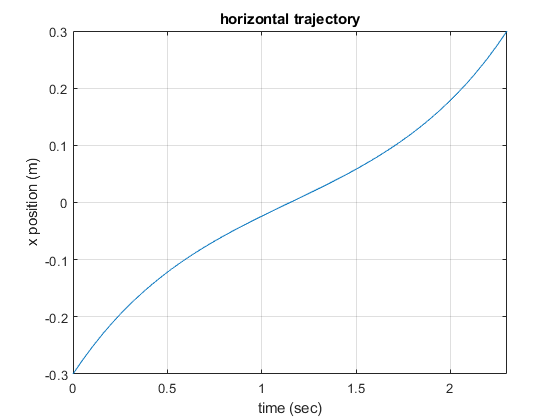


fplot(xSol_num, [0 double(Ts(2))])
grid on
title('horizontal trajectory')
xlabel('time (sec)');
ylabel('x position (m)')

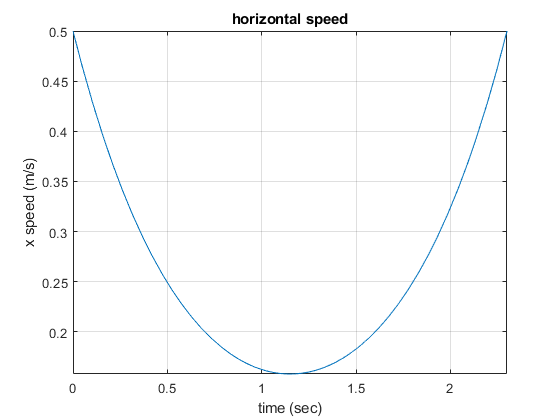


fplot(dxSol_num, [0 double(Ts(2))])
grid on
title('horizontal speed')
xlabel('time (sec)');
ylabel('x speed (m/s)')